# SAMPLE OF THE USE OF class_soil_ACAP (Model: ACAP)

## INPUTS:

Grain Size Distribution:

%       Particle Diameter       Aggregated Particle Volume passing
%       [m]                     [m3·m-3]
GSD = [ 0                       ,0;...
        2.00000000000000e-06    ,0.0200000000000000;...
        5.00000000000000e-05    ,0.130000000000000;...
        0.000106000000000000    ,0.256000000000000;...
        0.000250000000000000    ,0.743000000000000;...
        0.000500000000000000    ,0.916000000000000;...
        0.00100000000000000     ,0.985000000000000;...
        0.00200000000000000     ,0.997000000000000];

Porosity:

npor = 0.45;    

Input data for ACAP model:

optionsACAP  = struct('interpolation',struct(...
                        'fit_to_log',true,...
                        'extrapolate_dgmax',false),...
                     'wrc',struct(...
                        'saturation_vs_porosity',1.0,...
                        'opt_beta',6,...
                        'opt_Dg0',1'),...
                     'liquid',struct(...
                        'param_Ts',0.07197,...
                        'param_rhow',0.07197,...
                        'param_g',0.07197,...
                        'param_costheta',0.07197)...
             ); %Struct with options of the ACAP model  ;  

## CONSTRUCTION OF THE INSTANCE OF THE MODEL:

soil = class_soil_GSD_ACAP(...
    'GSD',GSD,...
    'npor',npor,...
    'beta',1.1,... %This in case of obp_beta=6 for betafixfit or opt_beta=0 for betaset
    'options',optionsACAP);

## EXAMPLES OF POSSIBLE OUTPUTS OF THE MODEL:

Grain Size in the GSD at 20% (D20) in [m]: 

disp(soil.Dg_FVg_from_GSD(0.2));

   8.2051e-05



Pore Size for the quantile 40% [m] (for the aggregated pore volume of 40% in the PSD) predicte from the GSD: 

disp(soil.Dp_Dg_from_GSD(soil.Dg_FVg_from_GSD(0.4)));

   7.4177e-05



Pore Size corresponding to the Particle diameter of 1E-4 [m] predicted with the model:

disp(soil.Dp_Dg_from_GSD(1E-4));

   4.2353e-05



 Pore Volume for the Pore size of 1E-4[m], on the PSD predicted with the model [per unit]:

disp(soil.FVp_Dp_from_GSD(1E-4));

    0.5463



Volumetric Water content for a suction of 1E-7[m] predicted by the model:

disp(soil.th_pp_from_GSD(1E-7));

     0



Suction [m] for a volumetric water content of 0.35 m3/m3:

disp(soil.pp_th_from_GSD(0.35));

   2.0595e+04



Suction [m] prediction for a relative saturation of 60%:

disp(soil.pp_Se_from_GSD(0.60));

   3.5790e+04



## PLOT OF THE PORE SIZE DISTRIBUION:

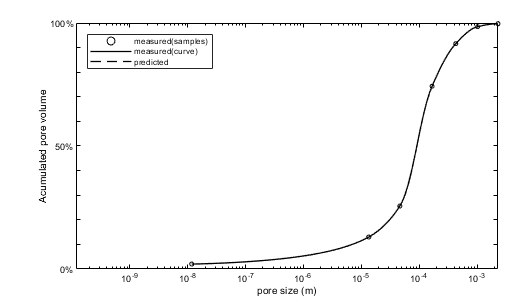

soilplot = class_soil_GSD_ACAP_PLOT(soil);
soilplot = soilplot.show_PSD('Pore Size Distribution (PSD)');
soilplot = soilplot.add_PSD_from_GSD(soil,'--',1,[0,0,0]);
legend({'measured(samples)','measured(curve)','predicted'},'Location','northwest');

## PLOT WATER RETENTION CURVE:

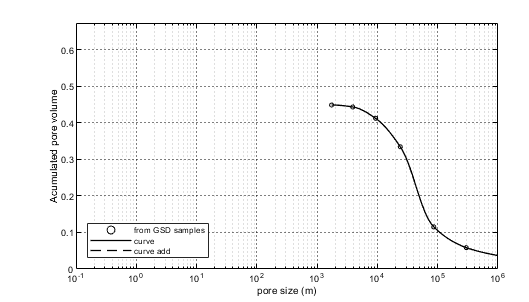

soilplot = class_soil_GSD_ACAP_PLOT(soil);
soilplot = soilplot.show_WRC('Water retention curve (WRC)');
soilplot = soilplot.add_WRC_from_GSD(soil,'--',1,[0,0,0]);
legend({'from GSD samples','curve','curve add'},'Location','southwest');

clear('alfa','GSD','npor','WRC','optionsACAP')
